# Code 1: Demonstrating regression bias with numerical thought experiment

by Nithin Sivadas; 29th March 2022

This code is a Gedankenexperiment/ numerical thought experiment exploring regression bias caused by uncertainties in the independent variable. Here we demonstrate non-linear biases in the regression functions caused by correlated uncertainties and non-gaussian pdfs. We also show that linear-least squares regression, orthogonal regression and non-linear regression are all susceptible to regression bias. Simple standard deviations aren't sufficient to describe uncertainties, and we need to consider how uncertainties are correlated with the magnitude of the measurement parameter or other parameters. The code is part of the following paper.   

Sivadas et al., 2022(a) Regression to the Mean in Solar Wind Measurements. *In preparation. (See section 2)*

*Required external packages: *

F. Carr (2022). Orthogonal Linear Regression (https://www.mathworks.com/matlabcentral/fileexchange/16800-orthogonal-linear-regression), MATLAB Central File Exchange. Retrieved April 19, 2022.

tic
setExportFig = 0;
outputFolder = 'G:\My Drive\Research\Projects\Sivadas_2022g\Figures\';

# Uncorrelated Gaussian Errors

## Uniform distribution

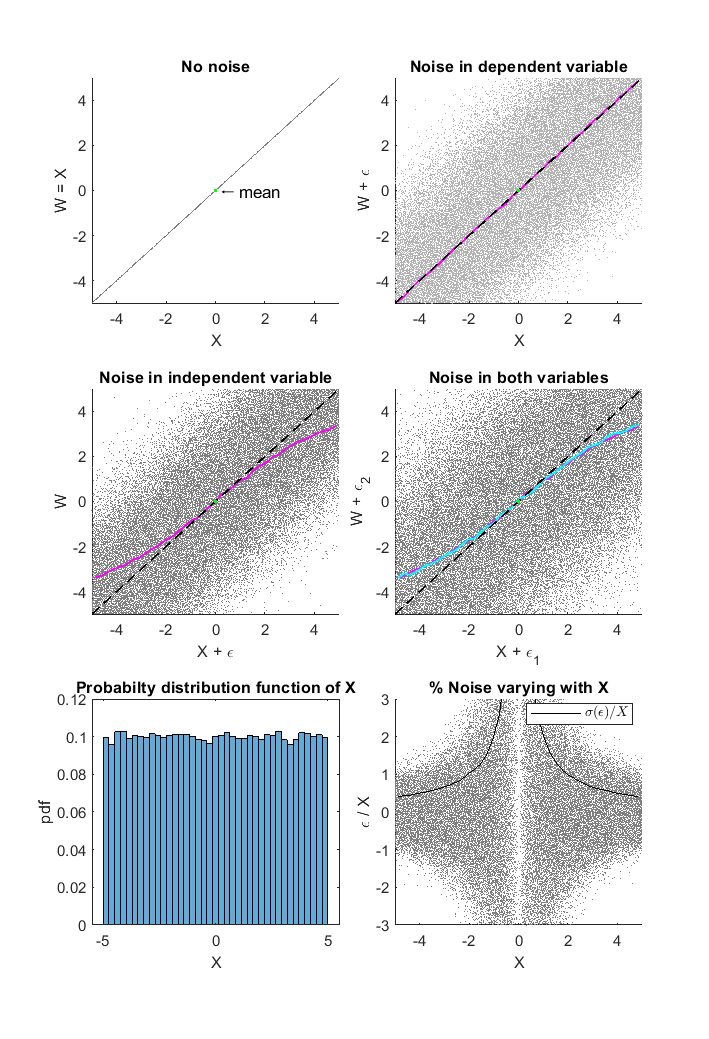

nSamples  = 100000;
nEnsembles = 1;

noiseAmp = 2;

X = random('Uniform',-5,+5,1,nSamples);
W = X;

W1 = W + noiseAmp.*random('Normal',0,1,1,nSamples);

XBin = linspace(min(X),max(X),40);
EWgX = create_curve(W',X',XBin);
EW1gX = create_curve(W1',X',XBin);


ni = noiseAmp.*random('Normal',0,1,1,nSamples);
 
X1 = X + ni;
EWgX1 = create_curve(W',X1',XBin);

X1 = X + noiseAmp.*random('Normal',0,1,1,nSamples);
EW1gX1 = create_curve(W1',X1',XBin);

f1 = figure;
resize_figure(f1,220,150);
plot_type0(X,W,X1,W1,EWgX1,EW1gX,EW1gX1,XBin,'linear');

if setExportFig
export_fig([outputFolder,'FigureS1.png'], ...
    '-r600','-png','-nocrop',f1);
export_fig([outputFolder,'FigureS1.pdf'], ...
    '-r600','-pdf','-nocrop',f1);
end

## Fig 1: Normal distribution

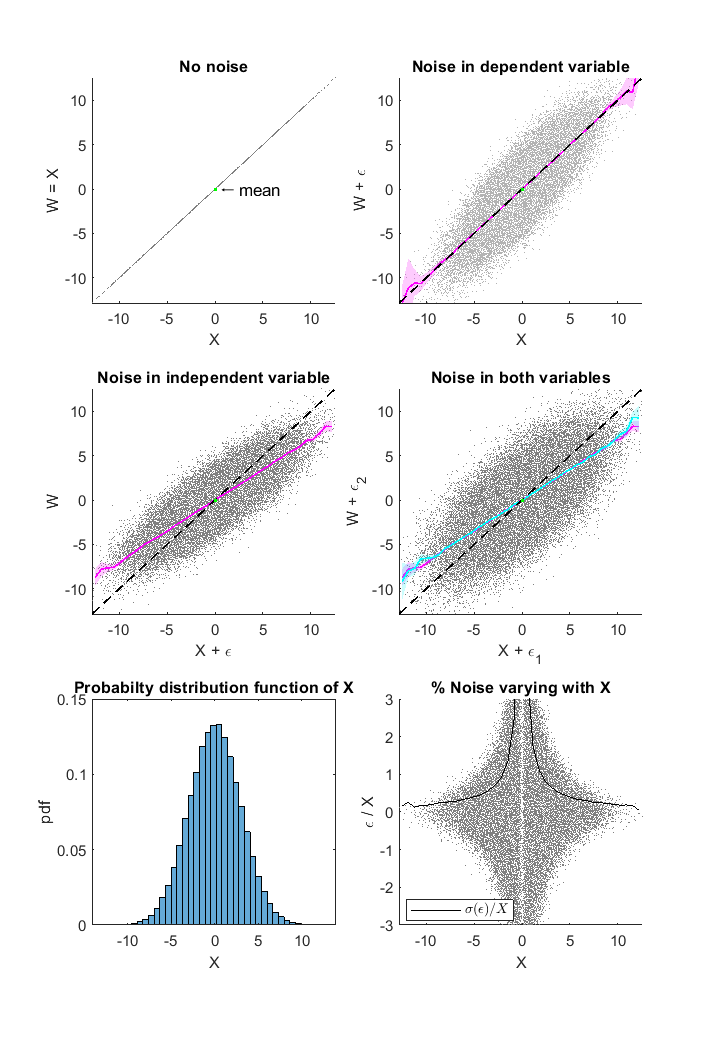

nSamples  = 100000;
nEnsembles = 1;

noiseAmp = 2;

X = random('Normal',0,3,1,nSamples);
W = X;

W1 = W + noiseAmp.*random('Normal',0,1,1,nSamples);

XBin = linspace(min(X),max(X),40);
EWgX = create_curve(W',X',XBin);
EW1gX = create_curve(W1',X',XBin);

X1 = X + noiseAmp.*random('Normal',0,1,1,nSamples);
EWgX1 = create_curve(W',X1',XBin);

X1 = X + noiseAmp.*random('Normal',0,1,1,nSamples);
EW1gX1 = create_curve(W1',X1',XBin);

f2 = figure;
resize_figure(f2,220,150);
plot_type0(X,W,X1,W1,EWgX1,EW1gX,EW1gX1,XBin,'linear');


if setExportFig
export_fig([outputFolder,'FigureS2.png'], ...
    '-r600','-png','-nocrop',f2);
export_fig([outputFolder,'FigureS2.pdf'], ...
    '-r600','-pdf','-nocrop',f2);
end

## Fig 3: Log-Normal distribution

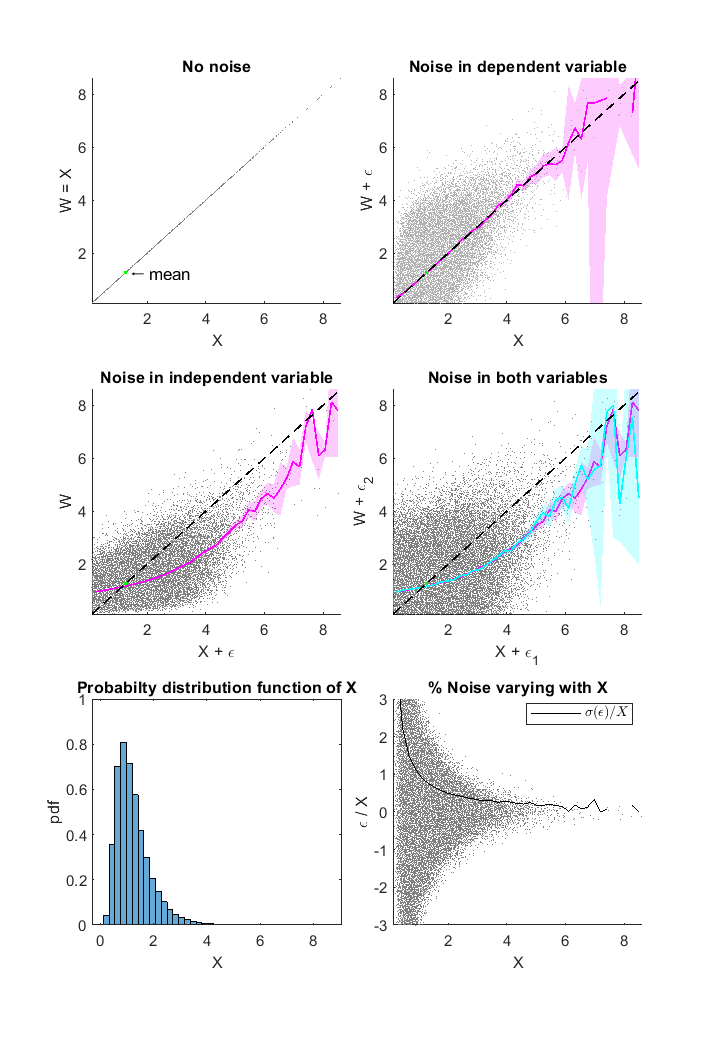

nSamples  = 100000;
nEnsembles = 1;

noiseAmp = 1;

X = random('Lognormal',0.1,0.5,1,nSamples);
W = X;

W1 = W + noiseAmp.*random('Normal',0,1,1,nSamples);

XBin = linspace(min(X),max(X),40);
EWgX = create_curve(W',X',XBin);
EW1gX = create_curve(W1',X',XBin);

X1 = X + noiseAmp.*random('Normal',0,1,1,nSamples);
EWgX1 = create_curve(W',X1',XBin);

X1 = X + noiseAmp.*random('Normal',0,1,1,nSamples);
EW1gX1 = create_curve(W1',X1',XBin);

f3 = figure;
resize_figure(f3,220,150);
plot_type0(X,W,X1,W1,EWgX1,EW1gX,EW1gX1,XBin,'linear');


if setExportFig
export_fig([outputFolder,'FigureS3.png'], ...
    '-r600','-png','-nocrop',f3);
export_fig([outputFolder,'FigureS3.pdf'], ...
    '-r600','-pdf','-nocrop',f3);
end

# Correlated Gaussian Errors

## Uniform distribution

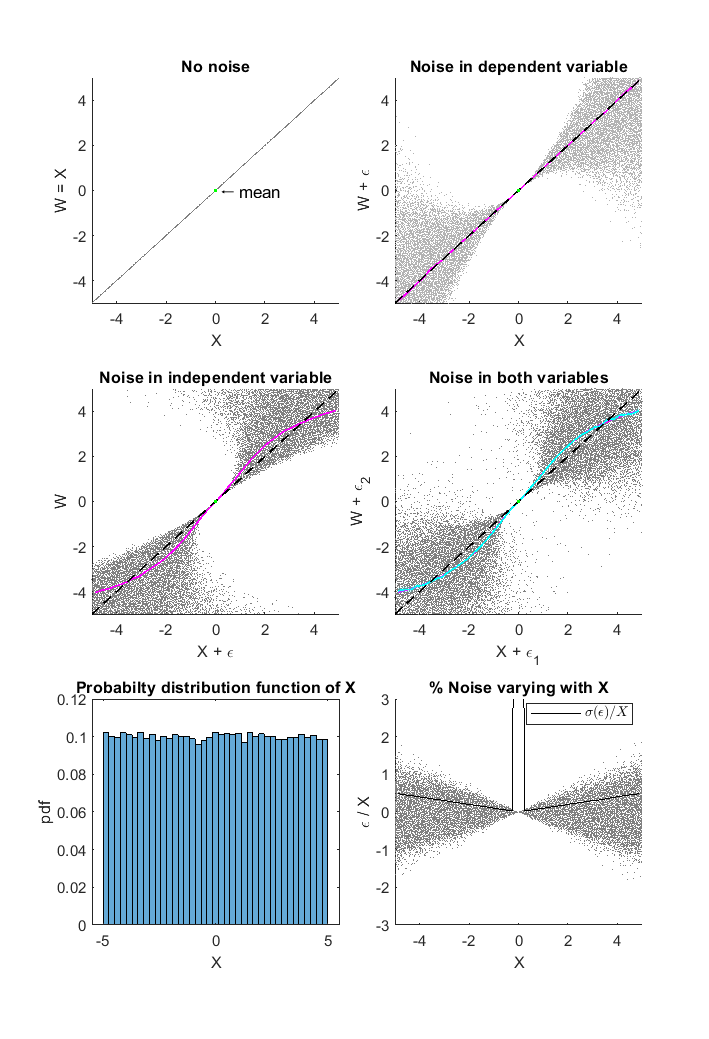

nSamples  = 100000;
nEnsembles = 1;

noiseAmp = 0.1;

X = random('Uniform',-5,+5,1,nSamples);
W = X;

W1 = W + noiseAmp.*W.^2.*random('Normal',0,1,1,nSamples);
X1 = X + noiseAmp.*X.^2.*random('Normal',0,1,1,nSamples);

XBin = linspace(min(X),max(X),40);
EWgX = create_curve(W',X',XBin);
EW1gX = create_curve(W1',X',XBin);


EWgX1 = create_curve(W',X1',XBin);

EW1gX1 = create_curve(W1',X1',XBin);

f4 = figure;
resize_figure(f4,220,150);
plot_type0(X,W,X1,W1,EWgX1,EW1gX,EW1gX1,XBin,'linear');


if setExportFig
export_fig([outputFolder,'FigureS4.png'], ...
    '-r600','-png','-nocrop',f4);
export_fig([outputFolder,'FigureS4.pdf'], ...
    '-r600','-pdf','-nocrop',f4);
end

## Normal distribution

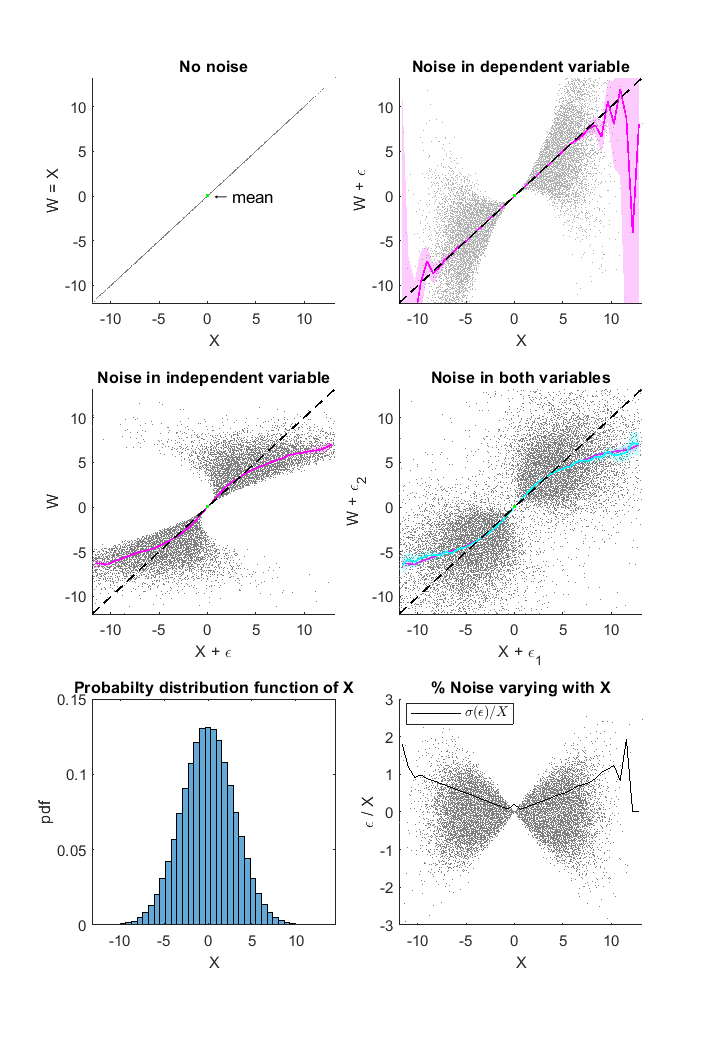

nSamples  = 100000;
nEnsembles = 1;

noiseAmp = 0.1;

X = random('Normal',0,3,1,nSamples);
W = X;

W1 = W + noiseAmp.*W.^2.*random('Normal',0,1,1,nSamples);
X1 = X + noiseAmp.*X.^2.*random('Normal',0,1,1,nSamples);

XBin = linspace(min(X),max(X),40);
EWgX = create_curve(W',X',XBin);
EW1gX = create_curve(W1',X',XBin);


EWgX1 = create_curve(W',X1',XBin);

EW1gX1 = create_curve(W1',X1',XBin);

f5 = figure;
resize_figure(f5,220,150);
plot_type0(X,W,X1,W1,EWgX1,EW1gX,EW1gX1,XBin,'linear');


if setExportFig
export_fig([outputFolder,'FigureS5.png'], ...
    '-r600','-png','-nocrop',f5);
export_fig([outputFolder,'FigureS5.pdf'], ...
    '-r600','-pdf','-nocrop',f5);
end

## Fig 4: Log-normal distribution

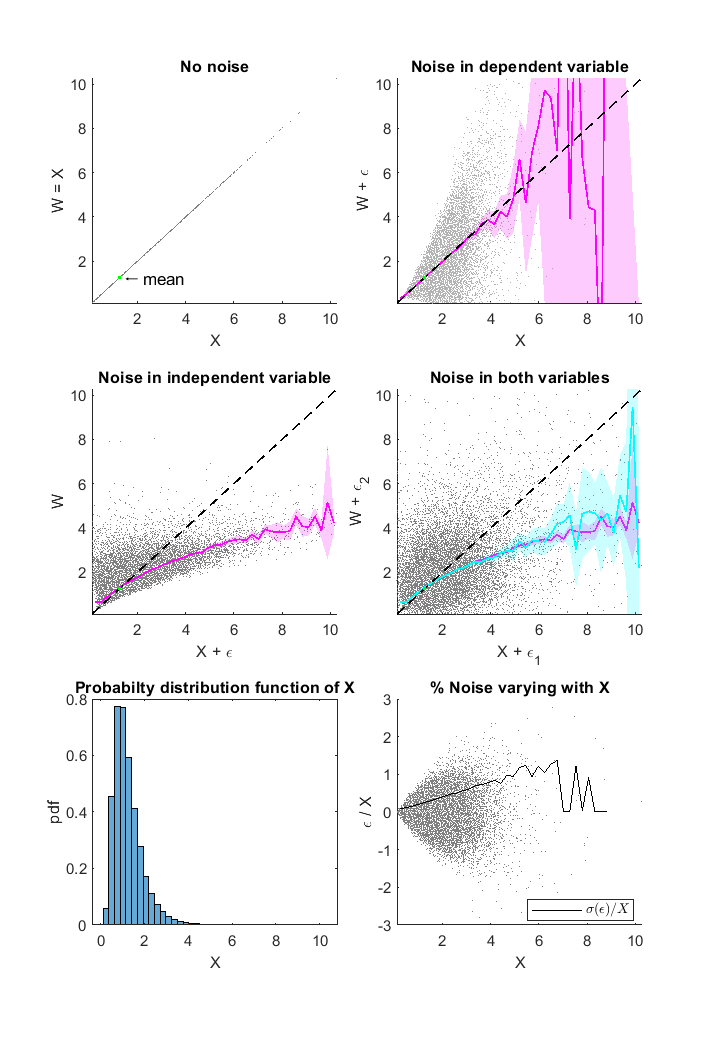

nSamples  = 100000;
nEnsembles = 1;

noiseAmp = 0.2;

X = random('Lognormal',0.1,0.5,1,nSamples);
W = X;

W1 = W + noiseAmp.*W.^2.*random('Normal',0,1,1,nSamples);
X1 = X + noiseAmp.*X.^2.*random('Normal',0,1,1,nSamples);

XBin = linspace(min(X),max(X),40);
EWgX = create_curve(W',X',XBin);
EW1gX = create_curve(W1',X',XBin);


EWgX1 = create_curve(W',X1',XBin);

EW1gX1 = create_curve(W1',X1',XBin);

f6 = figure;
resize_figure(f6,220,150);
plot_type0(X,W,X1,W1,EWgX1,EW1gX,EW1gX1,XBin,'linear');

if setExportFig
export_fig([outputFolder,'FigureS6.png'], ...
    '-r600','-png','-nocrop',f6);
export_fig([outputFolder,'FigureS6.pdf'], ...
    '-r600','-pdf','-nocrop',f6);
end


# Analysis

## How does regression bias affect the conditional pdfs?

nSamples  = 10000000;
nEnsembles = 1;

noiseAmp = 0.2;

X = random('Lognormal',0.1,0.5,nEnsembles,nSamples);
W = X;

X1 = X + noiseAmp.*X.^2.*random('Normal',0,1,nEnsembles,nSamples);

XBin = linspace(min(X),max(X),100);
EWgX1 = create_curve(W',X1',XBin);

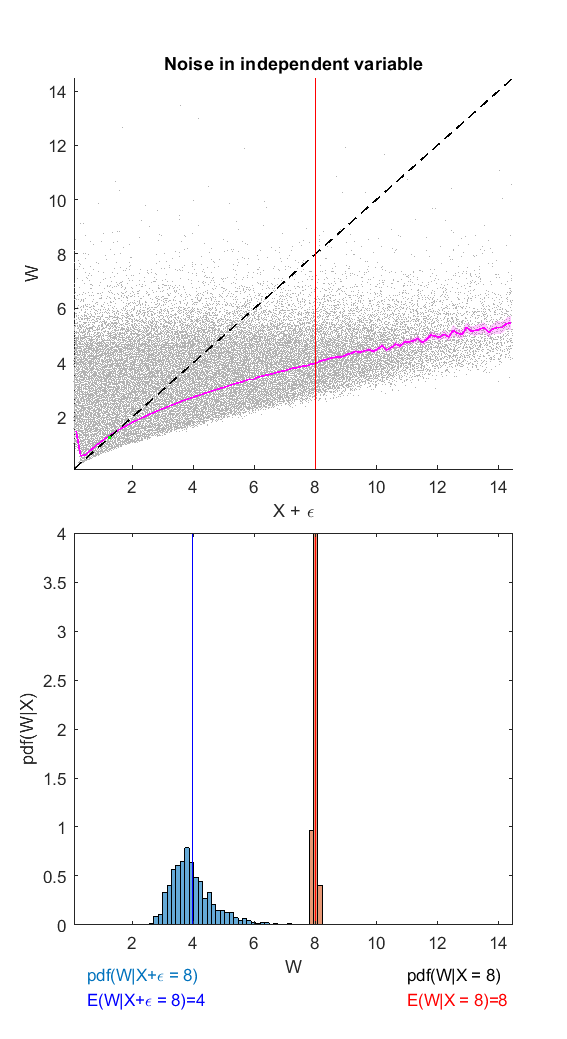

x = 8;

minx = x-0.1;
maxx = x+0.1;

f7 = figure; 
resize_figure(f7,220,120);
tiledlayout(2,1,"TileSpacing","tight");

nexttile
    scatter(X1,W,0.1,[0.7 0.7 0.7],'filled');
    hold on;
    plot_curve(EWgX1,'m');
    hold on;
    plot(XBin,XBin,'LineStyle','--','Color','k','LineWidth',1);
    plot(mean(X),mean(W),'.g');
    plot([mean(W(X>minx & X<maxx)),mean(W(X>minx & X<maxx))],[0, max(W)],'r');
    ylim([min(W),max(W)]);
    xlim([min(X),max(X)]);
    set(gca,'XScale','linear','YScale','linear');
    title('X vs. X+\epsilon')
    title('Noise in independent variable');
    xlabel('X + \epsilon');
    ylabel('W');

nexttile
    histogram(W(X1>minx & X1<maxx),XBin,'Normalization',"pdf");
    hold on;
    histogram(W(X>minx & X<maxx),XBin,'Normalization',"pdf");
    hold on;
    plot([mean(W(X1>minx & X1<maxx)),mean(W(X1>minx & X1<maxx))],[0, 4],'b');
    hold on;
    plot([mean(W(X>minx & X<maxx)),mean(W(X>minx & X<maxx))],[0, 4],'r');
    xlim([min(X),max(X)]);
    ylim([0,4]);
    xlabel('W');
    ylabel('pdf(W|X)');
    
    text(0.5,-0.5,['pdf(W|X+\epsilon = ',num2str(x,2),')'],'Color',[0 0.4470 0.7410]);
    text(0.5,-0.75,['E(W|X+\epsilon = ',num2str(x,2),')=',num2str(mean(W(X1>minx & X1<maxx)),2)],'Color','b','HorizontalAlignment',"left");
    text(11,-0.5,['pdf(W|X = ',num2str(x,2),')'],'Color','k');
    text(11,-0.75,['E(W|X = ',num2str(x,2),')=',num2str(mean(W(X>minx & X<maxx)),2)],'Color','r','HorizontalAlignment',"left");

% 
% if setExportFig
% export_fig([outputFolder,['FigureS7',num2str(x,2),'.png']], ...
%     '-r600','-png','-nocrop',f7);
% % export_fig([outputFolder,'FigureS7.pdf'], ...
% %     '-r600','-pdf','-nocrop',f7);
% end

## Fig 5: Comparing Linear Least-Squares, Orthogonal and Non-linear Regression

nSamples  = 100000;
nEnsembles = 1;

noiseAmp = 0.2;

X = random('Lognormal',0.1,0.5,1,nSamples);
W = X;

W1 = W + noiseAmp.*W.^2.*random('Normal',0,1,1,nSamples);
X1 = X + noiseAmp.*X.^2.*random('Normal',0,1,1,nSamples);

W2 = W + 0.8.*noiseAmp.*W.^2.*random('Normal',0,1,1,nSamples);
W3 = W + random('Normal',0,1,1,nSamples);

XBin = linspace(min(X),max(X),40);
EWgX = create_curve(W',X',XBin);
EW1gX = create_curve(W1',X',XBin);


EWgX1 = create_curve(W',X1',XBin);

EW1gX1 = create_curve(W1',X1',XBin);
EW2gX1 = create_curve(W2',X1',XBin);
EW3gX1 = create_curve(W3',X1',XBin);

options = fitoptions('Method', 'LinearLeastSquares','Robust','LAR');
fit_LLSE = fit(log10(X1'),log10(W'),'poly1',options);

fit_ortho =linortfit2(log10(X1'),log10(W'));

fit_LLSE2 = fit(log10(X1'),log10(W1'),'poly1',options);

fit_ortho2 =linortfit2(log10(X1'),log10(W1'));

fit_LLSE3 = fit(log10(X1'),log10(W2'),'poly1',options);

fit_ortho3 =linortfit2(log10(X1'),log10(W2'));

fit_LLSE4 = fit(log10(X1'),log10(W3'),'poly1',options);

fit_ortho4 =linortfit2(X1',W3');

x = 14;

minx = x-0.5;
maxx = x+0.5;
%%

f8 = figure;
resize_figure(f8,220,220);
tiledlayout(2,2,"TileSpacing","compact");
nexttile
    scatter(X1,W,0.4,0.5*[1 1 1],'filled');
    hold on;
    p1=plot_curve(EWgX1,'m');
    hold on;
    plot(XBin,XBin,'LineStyle','--','Color','k','LineWidth',1);
    hold on;
    plot(mean(X),mean(W),'.g'); 
    hold on;
    p2=plot(XBin,10.^fit_LLSE(log10(XBin)),'b');
    hold on;
    p3=plot(XBin,10.^(fit_ortho(2)+fit_ortho(1).*log10(XBin)),'Color',[0.8500 0.3250 0.0980],'LineWidth',1);

    ylim([min(W),max(W)]);
    xlim([min(X),max(X)]);
    set(gca,'XScale','linear','YScale','linear');
    title('X vs. X+\epsilon')
    title('Noise in independent variable');
    xlabel('X + \epsilon');
    ylabel('W');
    legend([p1,p2,p3],{'E(W|X+\epsilon) Non-linear regression','Linear Least-Squared Regression','Orthogonal Linear Regression'},'Location','northwest');

nexttile
    scatter(X1,W1,0.4,0.5*[1 1 1],'filled');
    hold on;
    plot_curve(EW1gX1,'m');
    hold on;
    plot(XBin,XBin,'LineStyle','--','Color','k','LineWidth',1);
    hold on;
    plot(mean(X),mean(W),'.g'); 
    hold on;
    plot(XBin,10.^fit_LLSE2(log10(XBin)),'b');
    hold on;
    plot(XBin,10.^(fit_ortho2(2)+fit_ortho2(1).*log10(XBin)),'Color',[0.8500 0.3250 0.0980],'LineWidth',1);

    ylim([min(W),max(W)]);
    xlim([min(X),max(X)]);
    set(gca,'XScale','linear','YScale','linear');
    title('Same noise in both variables');
    xlabel('X + \epsilon');
    ylabel('W + \epsilon');

nexttile
    scatter(X1,W2,0.4,0.5*[1 1 1],'filled');
    hold on;
    plot_curve(EW2gX1,'m');
    hold on;
    plot(XBin,XBin,'LineStyle','--','Color','k','LineWidth',1);
    hold on;
    plot(mean(X),mean(W),'.g'); 
    hold on;
    plot(XBin,10.^fit_LLSE3(log10(XBin)),'b');
    hold on;
    plot(XBin,10.^(fit_ortho3(2)+fit_ortho3(1).*log10(XBin)),'Color',[0.8500 0.3250 0.0980],'LineWidth',1);

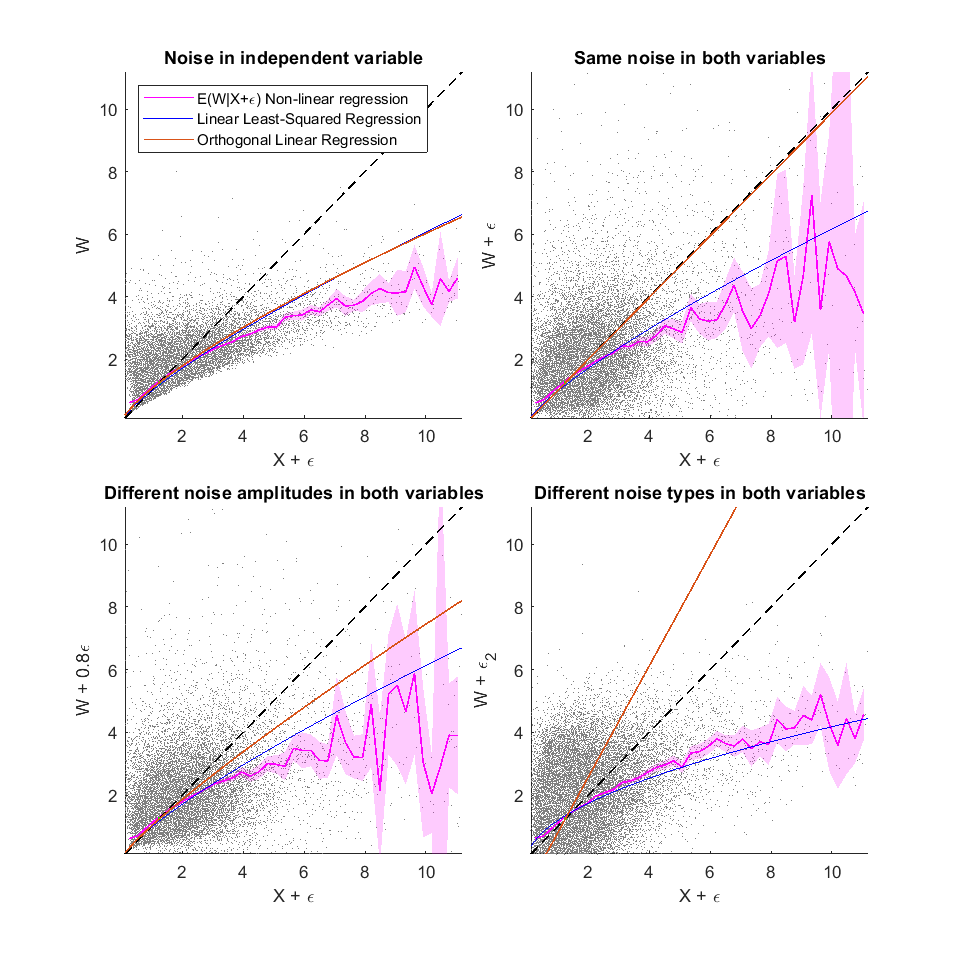

    ylim([min(W),max(W)]);
    xlim([min(X),max(X)]);
    set(gca,'XScale','linear','YScale','linear');
    title('Different noise amplitudes in both variables');
    xlabel('X + \epsilon');
    ylabel('W + 0.8\epsilon');

nexttile
    scatter(X1,W3,0.4,0.5*[1 1 1],'filled');
    hold on;
    plot_curve(EW3gX1,'m');
    hold on;
    plot(XBin,XBin,'LineStyle','--','Color','k','LineWidth',1);
    hold on;
    plot(mean(X),mean(W),'.g'); 
    hold on;
    plot(XBin,10.^fit_LLSE4(log10(XBin)),'b');
    hold on;
    plot(XBin,(fit_ortho4(2)+fit_ortho4(1).*(XBin)),'Color',[0.8500 0.3250 0.0980],'LineWidth',1);
    ylim([min(W),max(W)]);
    xlim([min(X),max(X)]);
    set(gca,'XScale','linear','YScale','linear');
    title('Different noise types in both variables');
    xlabel('X + \epsilon');
    ylabel('W + \epsilon_2');


if setExportFig
export_fig([outputFolder,'FigureS8.png'], ...
    '-r600','-png','-nocrop',f8);
export_fig([outputFolder,'FigureS8.pdf'], ...
    '-r600','-pdf','-nocrop',f8);
end


## Fig 6: Standard deviations of errors are not sufficient to describe regression bias

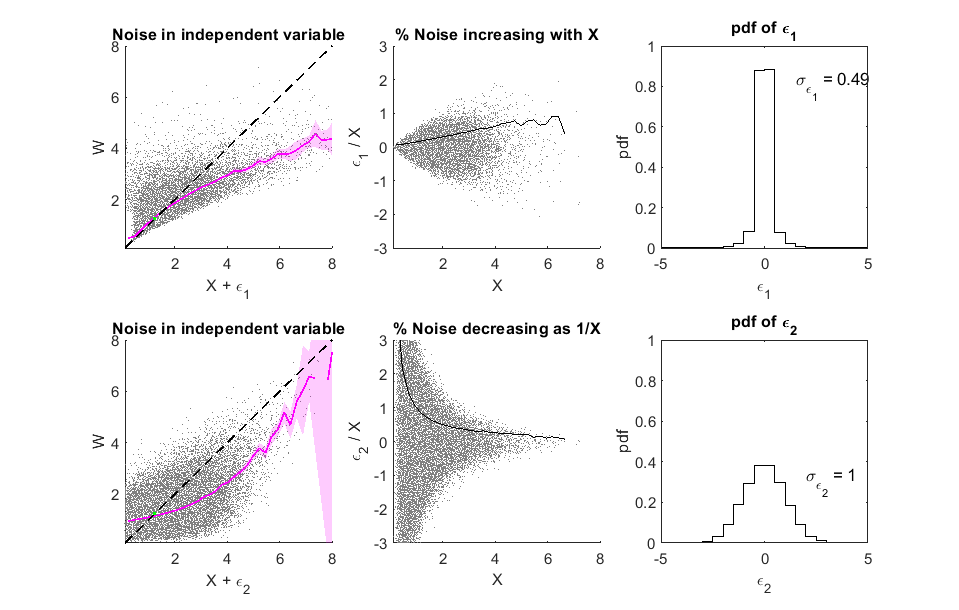

noiseAmp = 0.15;
nSamples = 100000;
X = random('Lognormal',0.1,0.5,1,nSamples);
W = X;

X1 = X + noiseAmp.*W.^2.*random('Normal',0,1,1,nSamples);
X2 = X + random('Normal',0,1,1,nSamples);    

XBin = linspace(min(X),max(X),40);
EWgX = create_curve(W',X',XBin);
EWgX1 = create_curve(W',X1',XBin);
EWgX2 = create_curve(W',X2',XBin);

f9 = figure;
resize_figure(f9,140,220);
tiledlayout(2,3,"TileSpacing","compact");
nexttile
    scatter(X1,W,0.4,0.5*[1 1 1],'filled');
    hold on;
    plot_curve(EWgX1,'m');
    hold on;
    plot(XBin,XBin,'LineStyle','--','Color','k','LineWidth',1);
    hold on;
    plot(mean(X),mean(W),'.g'); 
    ylim([min(W),8]);
    xlim([min(X),8]);
    set(gca,'XScale','linear','YScale','linear');
    title('Noise in independent variable');
    xlabel('X + \epsilon_1');
    ylabel('W');

nexttile
scatter(X,(X1-X)./X,0.5,0.5.*[1 1 1],'filled');
hold on;
Ee1gX = create_curve((X1'-X'),X',XBin);
plot(Ee1gX.XBins,Ee1gX.stdYgX./Ee1gX.XBins,'k');

    ylim([-3 3]);
    xlim([min(X),8]);
    xlabel('X');
    ylabel('\epsilon_1 / X');
    title('% Noise increasing with X')

nexttile
histogram((X1-X),-5:0.5:5,'Normalization','pdf','DisplayStyle','stairs','LineWidth',1,'EdgeColor','k');
    xlabel('\epsilon_1');
    text(1.5,0.8,['\sigma_{\epsilon_1} = ',num2str(std(X1-X),2)]);
    xlim([-5,+5]);
    ylim([0,1]);
    ylabel('pdf');
    title('pdf of \epsilon_1')

nexttile
    scatter(X2,W,0.4,0.5*[1 1 1],'filled');
    hold on;
    plot_curve(EWgX2,'m');
    hold on;
    plot(XBin,XBin,'LineStyle','--','Color','k','LineWidth',1);
    hold on;
    plot(mean(X),mean(W),'.g'); 
    ylim([min(W),8]);
    xlim([min(X),8]);
    set(gca,'XScale','linear','YScale','linear');
    title('Noise in independent variable');
    xlabel('X + \epsilon_2');
    ylabel('W');

nexttile
scatter(X,(X2-X)./X,0.5,0.5.*[1 1 1],'filled');
hold on;
Ee2gX = create_curve((X2'-X'),X',XBin);
plot(Ee2gX.XBins,Ee2gX.stdYgX./Ee2gX.XBins,'k');

    ylim([-3 3]);
    xlim([min(X),8]);
    xlabel('X');
    ylabel('\epsilon_2 / X');
    title('% Noise decreasing as 1/X')

nexttile
histogram((X2-X),-5:0.5:5,'Normalization','pdf','DisplayStyle','stairs','LineWidth',1,'EdgeColor','k');
    xlabel('\epsilon_2');
    text(2,0.3,['\sigma_{\epsilon_{2}} = ',num2str(std(X2-X),2)]);
    xlim([-5,+5]);
    ylim([0,1]);
    ylabel('pdf');
    title('pdf of \epsilon_2')


if setExportFig
export_fig([outputFolder,'FigureS9.png'], ...
    '-r600','-png','-nocrop',f9);
export_fig([outputFolder,'FigureS9.pdf'], ...
    '-r600','-pdf','-nocrop',f9);
end

## Fig 2: Simple explanation of regerssion to the mean

noiseAmp = 2;
nSamples = 100000;
X = 3.*random('Normal',0,1,1,nSamples);
[fX,xbin]=ksdensity(X,-10:0.1:10,'Bandwidth',1);
im=2;
fm=4;
[fX_noise_2,xbin]=ksdensity(im+noiseAmp.*random('Normal',0,1,1,nSamples),-10:0.1:10,'Bandwidth',1);
[fX_noise_4,xbin]=ksdensity(fm+noiseAmp.*random('Normal',0,1,1,nSamples),-10:0.1:10,'Bandwidth',1);

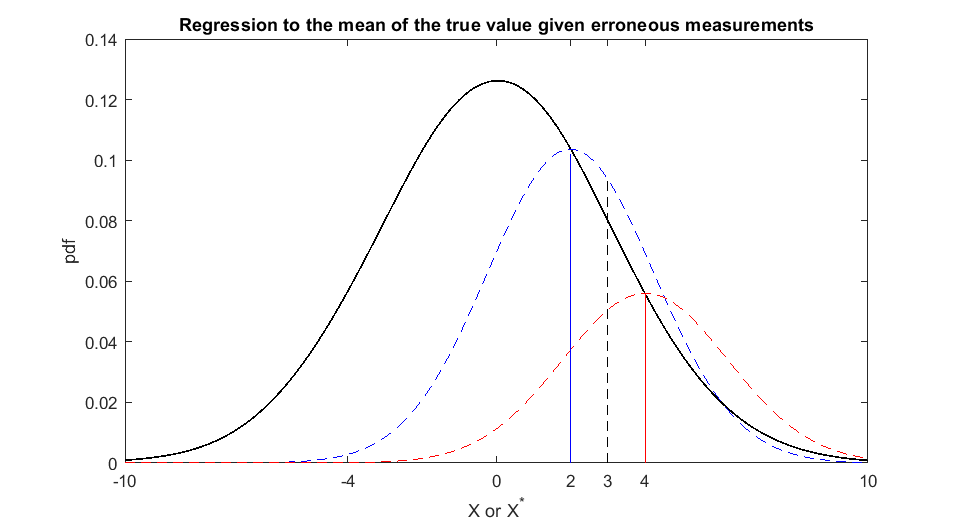

f10=figure;
resize_figure(f10,120,220);
plot(xbin,fX,'k','LineWidth',1);
hold on;
plot(xbin,fX(xbin==im).*fX_noise_2./(max(fX_noise_2)),'--b');
% plot(xbin,fX(xbin==3).*fX_noise_3./(max(fX_noise_2)));
plot(xbin,fX(xbin==fm).*fX_noise_4./(max(fX_noise_2)),'--r');
plot([3,3],[0,0.093],'--k');
hold on;
plot([2,2],[0,0.102],'b');
hold on;
plot([4,4],[0,0.056],'r');
title('Regression to the mean of the true value given erroneous measurements');
xlabel('X or X^*');
ylabel('pdf');
set(gca,'XTick',[-10,-4,0,2,3,4,10]);

if setExportFig
export_fig([outputFolder,'FigureS10.png'], ...
    '-r600','-png','-nocrop',f10);
export_fig([outputFolder,'FigureS10.pdf'], ...
    '-r600','-pdf','-nocrop',f10);
end
toc

## **Functions**

function plot_type0(X,W,X1,W1,EWgX1,EW1gX,EW1gX1,XBin,Scale)
    tiledlayout(3,2,'TileSpacing',"compact");
    
    nexttile
    scatter(X,W,0.1,0.5.*[1 1 1],'filled');
    set(gca,'XScale',Scale,'YScale',Scale);
    hold on;
    plot(mean(X),mean(W),'.g');
    text(mean(X),mean(W),' 🠐 mean',"HorizontalAlignment","left");
    title('No noise');
    xlabel('X');
    ylabel('W = X');
    ylim([min(W),max(W)]);
    xlim([min(X),max(X)]);
    %% Regression curve with noise only on W
    nexttile
    
    scatter(X,W1,0.1,[0.7 0.7 0.7],'filled',"o");
    hold on;
    plot_curve(EW1gX,'m');
    hold on;
    plot(XBin,XBin,'LineStyle','--','Color','k','LineWidth',1);
    plot(mean(X),mean(W),'.g');
    ylim([min(W),max(W)]);
    xlim([min(X),max(X)]);
    set(gca,'XScale',Scale,'YScale',Scale);
    title('Noise in dependent variable');
    xlabel('X');
    ylabel('W + \epsilon');
    
    %% Regression curve with noise only on X
    nexttile
    
    scatter(X1,W,0.1,0.5.*[1 1 1],'filled');
    hold on;
    plot_curve(EWgX1,'m');
    hold on;
    plot(XBin,XBin,'LineStyle','--','Color','k','LineWidth',1);
    plot(mean(X),mean(W),'.g');
    ylim([min(W),max(W)]);
    xlim([min(X),max(X)]);
    set(gca,'XScale',Scale,'YScale',Scale);
    title('X vs. X+\epsilon')
    title('Noise in independent variable');
    xlabel('X + \epsilon');
    ylabel('W');
    %% Regression curve with noise in X & W
    
    nexttile
    
    scatter(X1,W1,0.1,0.5.*[1 1 1],'filled');
    hold on;
    plot_curve(EWgX1,'m');
    hold on;
    plot_curve(EW1gX1,'c');
    hold on;
    plot(XBin,XBin,'LineStyle','--','Color','k','LineWidth',1);
    plot(mean(X),mean(W),'.g');
    ylim([min(W),max(W)]);
    xlim([min(X),max(X)]);
    set(gca,'XScale',Scale,'YScale',Scale);
    title('X+\epsilon vs. X+\epsilon')
    title('Noise in both variables');
    xlabel('X + \epsilon_1');
    ylabel('W + \epsilon_2');
    
    nexttile
    histogram(X,'BinEdges',XBin,'Normalization',"pdf");
    xlabel('X');
    ylabel('pdf');
    title('Probabilty distribution function of X')
    
    ax2=nexttile;
    scatter(X,(X1-X)./X,0.5,0.5.*[1 1 1],'filled');
    EegX = create_curve((X1'-X'),X',XBin);
    hold on;
    p1=plot(EegX.XBins,EegX.stdYgX./abs(EegX.XBins),'k');
    legend(ax2,p1,'$\sigma(\epsilon)/X$','interpreter','latex','Location','best');
    ylim([-3 3]);
    xlim([min(X),max(X)]);
    xlabel('X');
    ylabel('\epsilon / X');
    title('% Noise varying with X')
end

function p = plot_curve(curve, color)

CI1 = interp_nans(curve.CI);
p=plot(curve.XBins, curve.YgX, 'Color', color,'LineWidth',1);
hold on;
plot_ci(curve.XBins,CI1,color,0.2);
end

function plot_ci(x,ci,color,alpha)
    hold on;
    X2 = [x, fliplr(x)];
    inBetween = [ci(:,1)', fliplr(ci(:,2)')];
    fill(X2,inBetween,color,'LineStyle','none','FaceAlpha',alpha);
end

function curve = create_curve(Y, X, Ei)
% Y - first variable, X - second variable, Ei - bin array
if nargin<3
    Ei = 100;
end
Y = Y(:);
Y(Y==999999)=nan;

X1 = X(~isnan(X) & ~isnan(Y));
Y1 = Y(~isnan(X) & ~isnan(Y));
X = X1;
Y = Y1;

[xindx, E] = discretize(X(:),Ei);

for i = 1:max(xindx)
    curve.YgX(i) = nanmean(Y(xindx==i));
    curve.stdYgX(i) = nanstd(Y(xindx==i));
    curve.NSamples(i) = sum(xindx==i & ~isnan(Y));
    curve.SEM(i) = nanstd(Y(xindx==i))./sqrt(curve.NSamples(i));
    curve.ts(i,:) = tinv([0.025 0.975],curve.NSamples(i)-1);
    curve.CI(i,:) = curve.YgX(i) + curve.ts(i,:)*curve.SEM(i);
    curve.XBins(i) = 0.5*(E(i)+E(i+1));
end

curve.E = E; 

end

%%

# External Functions

Acknowledging the use of these external functions: 

- F. Carr (2022). Orthogonal Linear Regression (https://www.mathworks.com/matlabcentral/fileexchange/16800-orthogonal-linear-regression), MATLAB Central File Exchange. Retrieved April 19, 2022.

 
function [p] = linortfit2(xdata, ydata)
% LINORTFIT2  Fit a line to data by ORTHOGONAL least-squares.
%    P = LINORTFIT2(X,Y) finds the coefficients of a 1st-order polynomial
%    that best fits the data (X,Y) in an ORTHOGONAL least-squares sense.
%    Consider the line P(1)*t + P(2), and the minimum (Euclidean) distance
%    between this line and each datapoint [X(i) Y(i)] -- LINORTFIT2 finds
%    P(1) and P(2) such that the sum of squared distances is minimized.
if ~isequal(size(xdata), size(ydata))
    error('linortfit2:XYSizeMismatch',...
          'X and Y vectors must be the same size.');
end
[N,C] = linortfitn([xdata(:) ydata(:)]);
% The hyperplane given by N * [x; y] + C == 0 is optimal.
% Convert to the form  y = p(1)*x + p(2), just like polyfit(xdata,ydata,1).
p = - [N(1)  C] / N(2);
end

function [hyperplane_normal, hyperplane_offset] = linortfitn(data)
% LINORTFITN  Fit a line to data by ORTHOGONAL least-squares.
%    [N,C] = LINORTFITN(DATA) finds the coefficients of a hyperplane (in
%    Hessian normal form) that best fits the data in an ORTHOGONAL
%    least-squares sense.  Consider the hyperplane
%       H = {x | dot(N,x) + C == 0},
%    and the minimum (Euclidean) distance between this hyperplane and each
%    datapoint DATA(i,:) -- LINORTFITN finds N and C such that the sum of
%    squared distances is minimized.
[M,N] = size(data);
if M <= N,
    error('linortfitn:DegenerateProblem',...
        'There are fewer datapoints than dimensions: the data is perfectly fit by a hyperplane.');
end
[U,S,V] = svd(data - repmat(mean(data),M,1), 0);
hyperplane_normal = V(:,end);
hyperplane_offset = - mean(data * hyperplane_normal);
end